## Attention: Most of the Question about functions are explained at the bottom of the live script.

# PART 1) DTFT

#### 1) For plotting and constructing these signals, at first we should produce $R_m \left\lbrack n\right\rbrack$ with m$\epsilon${10,25,50,101}.

x1 = 0:1:10;
x2 = 0:1:25;
x3 = 0:1:50;
x4 = 0:1:101;
R1 = 0;
for i = 1:length(x1)-1
    R1(i) = 1;
end
R2 = 0;
for i = 1:length(x2)-1
    R2(i) = 1;
end
R3 = 0;
for i = 1:length(x3)-1
    R3(i) = 1;
end
R4 = 0;
for i = 1:length(x4)-1
    R4(i) = 1;
end

#### After defining $R_m \left\lbrack n\right\rbrack$, we take those signals to DTFT function that have been explained down below and plot the magnitude of the normalized signal.

[X1,w1] = dtft_manual(R1,x1);
plot(w1, abs(X1)/max(X1))

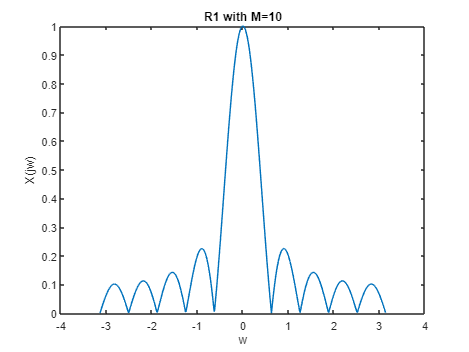

title('R1 with M=10')
xlabel('w'); ylabel('X(jw)');

[X2,w2] = dtft_manual(R2,x2);
plot(w2, abs(X2)/max(X2))

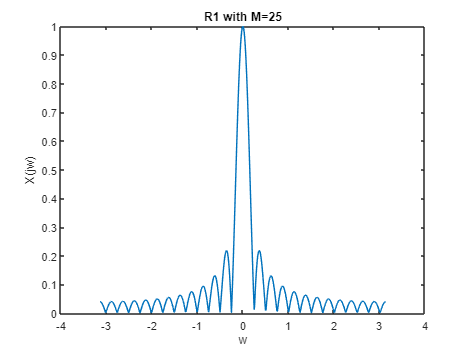

title('R1 with M=25')
xlabel('w'); ylabel('X(jw)');

[X3,w3] = dtft_manual(R3,x3);
plot(w3, abs(X3)/max(X3))

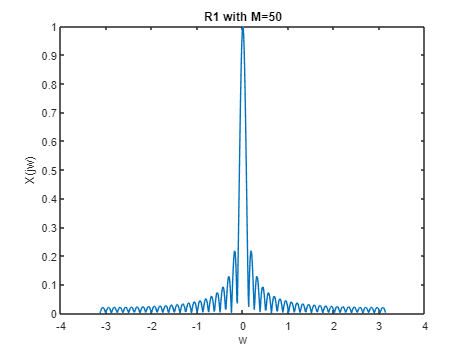

title('R1 with M=50')
xlabel('w'); ylabel('X(jw)');

[X4,w4] = dtft_manual(R4,x4);
plot(w4, abs(X4)/max(X4))

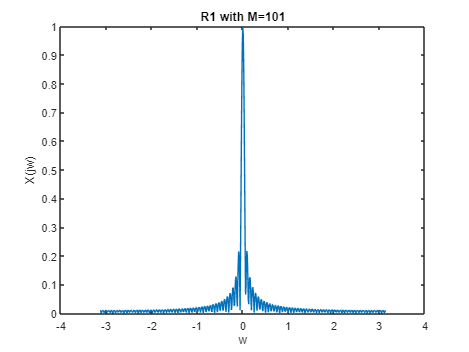

title('R1 with M=101')
xlabel('w'); ylabel('X(jw)');

#### As we increase the number of M, in frequency domain, the signal will be shriked and has more changes in $\omega$ and get closer to delta function.

#### 

# 
$$C_M \left\lbrack n\right\rbrack$$


c_temp = zeros(1,length(x1)-1);
for i = 1:length(x1)-1
    c_temp(i) = (0.5).*(1 - cos((2*pi*i)/x1(11)-1));
end
c1 = c_temp.*R1;
[C1, w1]=dtft_manual(c1,x1);
plot(w1, abs(C1)/max(C1));

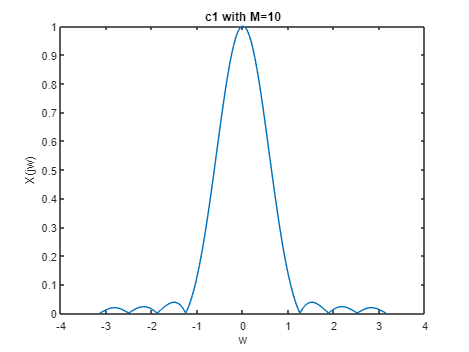

title('c1 with M=10')
xlabel('w'); ylabel('X(jw)');

c_temp = zeros(1,length(x2)-1);
for i = 1:length(x2)-1
    c_temp(i) = (0.5).*(1 - cos((2*pi*i)/x2(26)-1));
end
c2 = c_temp.*R2;
[C2, w2]=dtft_manual(c2,x2);
plot(w2, abs(C2)/max(C2))

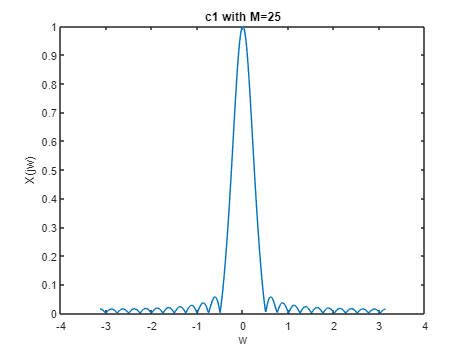

title('c1 with M=25')
xlabel('w'); ylabel('X(jw)');

c_temp = zeros(1,length(x3)-1);
for i = 1:length(x3)-1
    c_temp(i) = (0.5).*(1 - cos((2*pi*i)/x3(51)-1));
end
c3 = c_temp.*R3;
[C3, w3]=dtft_manual(c3,x3);
plot(w3, abs(C3)/max(C3))

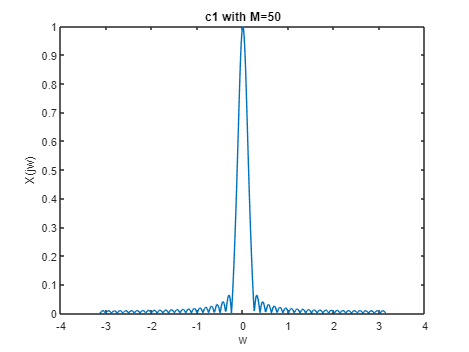

title('c1 with M=50')
xlabel('w'); ylabel('X(jw)');

c_temp = zeros(1,length(x4)-1);
for i = 1:length(x4)-1
    c_temp(i) = (0.5).*(1 - cos((2*pi*i)/x4(102)-1));
end
c4 = c_temp.*R4;
[C4, w4]=dtft_manual(c4,x4);
plot(w4, abs(C4)/max(C4))

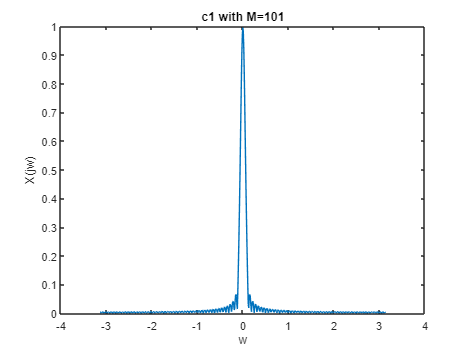

title('c1 with M=101')
xlabel('w'); ylabel('X(jw)');

#### With increas of M, the denominator of $\mathrm{c}\mathrm{o}\mathrm{s}\left(\frac{2\pi n}{M-1}\right)$ will be bigger so it will be compressed in frequency domain.

# 
$$\tau_M \left\lbrack n\right\rbrack$$


taw_temp = zeros(1,length(x1)-1);
for i = 1:length(x1)-1
    taw_temp(i) = 1 - (abs(x1(11) - 1 - (2*i)))/(x1(11) - 1);
end
taw1 = taw_temp.*R1;
[Taw1, w1]=dtft_manual(taw1,x1);
plot(w1, abs(Taw1)/max(Taw1))

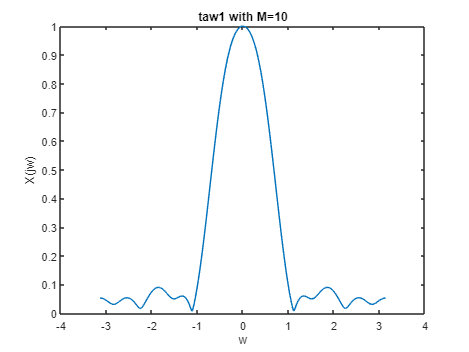

title('taw1 with M=10')
xlabel('w'); ylabel('X(jw)');

taw_temp = zeros(1,length(x2)-1);
for i = 1:length(x2)-1
    taw_temp(i) = 1 - (abs(x2(26) - 1 - (2*i)))/(x2(26) - 1);
end
taw2 = taw_temp.*R2;
[Taw2, w2]=dtft_manual(taw2,x2);
plot(w2, abs(Taw2)/max(Taw2))

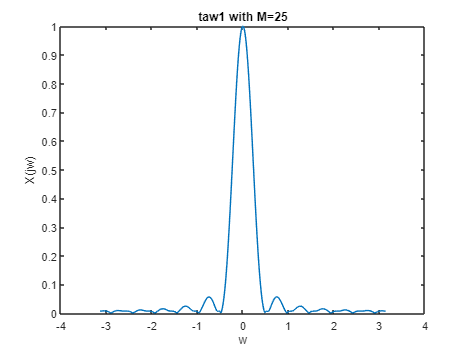

title('taw1 with M=25')
xlabel('w'); ylabel('X(jw)');

taw_temp = zeros(1,length(x3)-1);
for i = 1:length(x3)-1
    taw_temp(i) = 1 - (abs(x3(51) - 1 - (2*i)))/(x3(51) - 1);
end
taw3 = taw_temp.*R3;
[Taw3, w3]=dtft_manual(taw3,x3);
plot(w3, abs(Taw3)/max(Taw3))

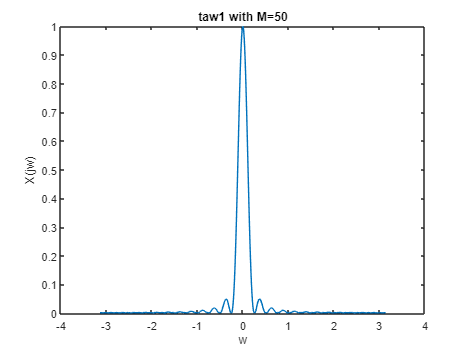

title('taw1 with M=50')
xlabel('w'); ylabel('X(jw)');

taw_temp = zeros(1,length(x4)-1);
for i = 1:length(x4)-1
    taw_temp(i) = 1 - (abs(x4(102) - 1 - (2*i)))/(x4(102) - 1);
end
taw4 = taw_temp.*R4;
[Taw4, w4]=dtft_manual(taw4,x4);
plot(w4, abs(Taw4)/max(Taw4))

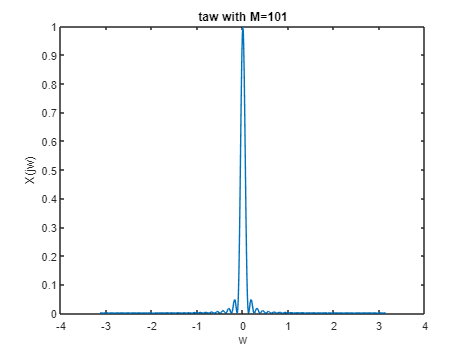

title('taw with M=101')
xlabel('w'); ylabel('X(jw)');

#### As the number of M increases, the n in numerator of signal, will be cancled so it converges to unit step with the DTFT of delta.

4)

H_temp = zeros(1,length(x1)-1);
for i = 1:length(x1)-1
    H_temp(i) = 0.54 - 0.46*cos(2*pi*i)/(x1(11)-1);
end
h1 = H_temp.*R1;
[H1, w1]=dtft_manual(h1,x1);
plot(w1, abs(H1)/max(H1))

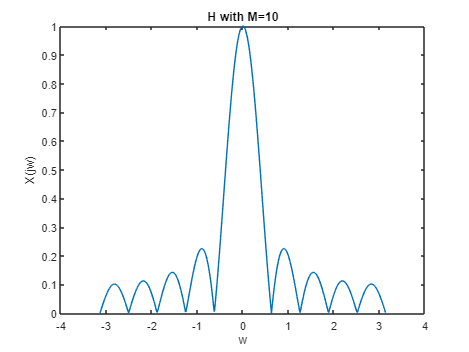

title('H with M=10')
xlabel('w'); ylabel('X(jw)');

H_temp = zeros(1,length(x2)-1);
for i = 1:length(x2)-1
    H_temp(i) = 0.54 - 0.46*cos(2*pi*i)/(x2(26)-1);
end
h2 = H_temp.*R2;
[H2, w2]=dtft_manual(h2,x2);
plot(w2, abs(H2)/max(H2))

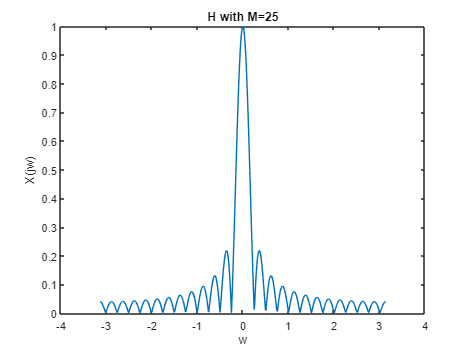

title('H with M=25')
xlabel('w'); ylabel('X(jw)');

H_temp = zeros(1,length(x3)-1);
for i = 1:length(x3)-1
    H_temp(i) = 0.54 - 0.46*cos(2*pi*i)/(x3(51)-1);
end
h3 = H_temp.*R3;
[H3, w3]=dtft_manual(h3,x3);
plot(w3, abs(H3)/max(H3))

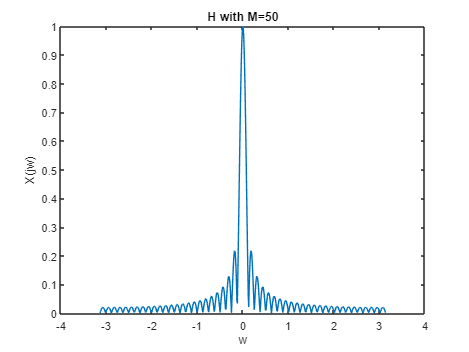

title('H with M=50')
xlabel('w'); ylabel('X(jw)');

H_temp = zeros(1,length(x4)-1);
for i = 1:length(x4)-1
    H_temp(i) = 0.54 - 0.46*cos(2*pi*i)/(x4(102)-1);
end
h4 = H_temp.*R4;
[H4, w4]=dtft_manual(h4,x4);
plot(w4, abs(H4)/max(H4))

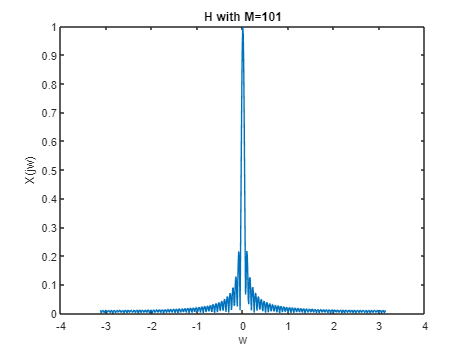

title('H with M=101')
xlabel('w'); ylabel('X(jw)');

#### As the increment of M, the $2\pi \frac{n}{\left(M-1\right)}$ factor will be little and $\textrm{Cos}\left(2\pi \frac{n}{\left(M-1\right)}\right)$ be closer to one and the whole signal will be like 0.08*$R_M \left\lbrack n\right\rbrack \ldotp$

#### 2)

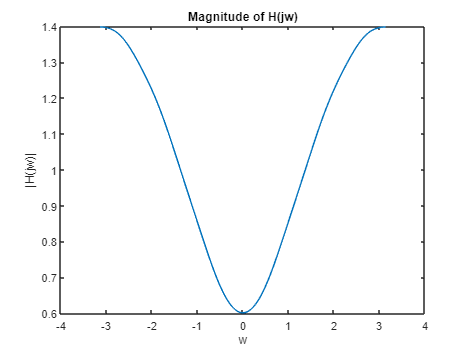

b = [1 0 0 0 0 0 0];
a = [(0.4) (0.4)^2 (0.4)^3 (0.4)^4 (0.4)^5 (0.4)^6];
w = -pi:0.01:pi;
H1_jw = diff_resp(a,b,w);
plot(w,abs(H1_jw))
title('Magnitude of H(jw)')
xlabel('w')
ylabel('|H(jw)|')

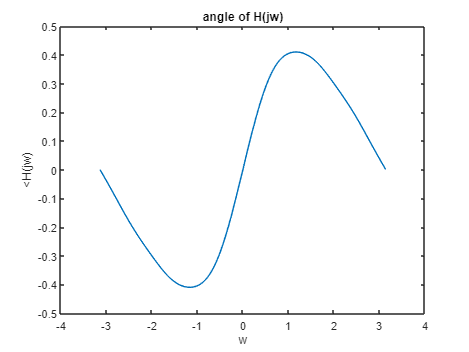

plot(w,phase(H1_jw))
title('angle of H(jw)')
xlabel('w')
ylabel('<H(jw)')

#### The magnitude and phase of $H\left(e^{j\omega } \right)$ is shown above.

#### 1-3)

n = 0:200;
x1_n = 1 + cos((pi*n + pi)/2);
b = [1 0 1 0 1 0 1];
a = [1 0 0.7 0 0.49 0 0.343];
y2 = filter(b,a,x1_n)

y2 =     1.0000         0    1.3000    2.0000    1.6000    0.6000    1.9000    2.6000    1.4401    1.2000    1.5121    1.6802    1.5842    1.3441    1.6562    1.8243    1.5458    1.4881    1.5631    1.6034    1.5804    1.5227    1.5977    1.6380    1.5711    1.5573    1.5753    1.5850    1.5794    1.5656    1.5836    1.5933    1.5772    1.5739    1.5782    1.5806    1.5792    1.5759    1.5802    1.5825    1.5787    1.5779    1.5789    1.5795    1.5792    1.5784    1.5794    1.5800    1.5790    1.5789


x2_n = 1 + 2*cos((pi*n)/4) + 3*cos((pi*n)/2) + 4*cos((3*pi*n)/4) + 5*cos(pi*n) + 6*cos((5*pi*n)/4);
b = [1 0 1 0 1 0 1];
a = [1 0 0.7 0 0.49 0 0.343];
y2 = filter(b,a,x2_n)

y2 =    21.0000   -9.6569    9.3000   -1.2402    4.2000   -0.7431    9.3000  -11.5598   12.2421   -7.1186    9.4329   -5.0978    8.2084   -4.9784    9.4329   -7.5755   10.1393   -6.5092    9.4648   -6.0240    9.1708   -5.9953    9.4648   -6.6189    9.6345   -6.3629    9.4725   -6.2464    9.4019   -6.2395    9.4725   -6.3892    9.5132   -6.3277    9.4743   -6.2998    9.4574   -6.2981    9.4743   -6.3340    9.4841   -6.3193    9.4748   -6.3126    9.4707   -6.3122    9.4748   -6.3208    9.4771   -6.3173


# PART 2) INTERPOLATION

#### 2-1) At first, we define the mentioned interval and with the step_size = 0.01.

#### then, by moving through the defined interval, the Sinc function will be produced which is can be shown in below.

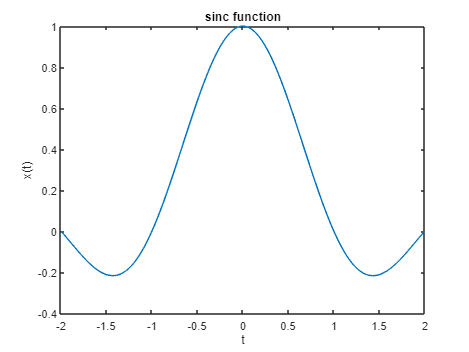

t = -2:0.01:2;

fs1=200; %sampling rate
dt1=1/fs1;  %sampling interval
t1=-2:dt1:2-dt1;
xc_t = sinc(t1);
plot(t1,xc_t);
title('sinc function');
xlabel('t'); ylabel('x(t)');

#### for smapling the signal at 8 Hz frequency, we go through the signal with steps of f_countinuous/f_discrete and we have to define new interval which is f_discrete times bigger than the continuous interval (because of sampling)

f2 = 8;
xd_t = xc_t(1:fs1/f2:length(xc_t));
n_d = (-2*f2):(2*f2);

[comp2, M2] = compressor(xd_t,n_d, 2);

[comp4,M4] = compressor(xd_t,n_d, 4);

### compressor function which is at the end of the live script, takes sample by the rate of M. It also changes the signal's interval by the dactor of 1/M.

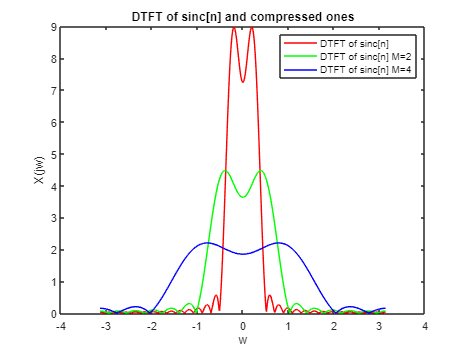

[X_main, w] = dtft_manual(xd_t, n_d);
[X_comp2,w] = dtft_manual(comp2, M2);
[X_comp4,w] = dtft_manual(comp4, M4);
plot(w,abs(X_main),'r',w,abs(X_comp2),'g',w,abs(X_comp4),'b');
title('DTFT of sinc[n] and compressed ones')
xlabel('w'); ylabel('X(jw)');
legend('DTFT of sinc[n]','DTFT of sinc[n] M=2','DTFT of sinc[n] M=4')

#### As can be seen in figure above, as we compress the signal by different M's, the maximum of signal changes by 1/M factor 

#### and $\omega$  axis will be expanded by factor M.

#### 
$$\sum_{n=0}^M x{\left[nM\right]}e^{-j\omega n} =\frac{1}{M}\sum_{n=0}^M X{\left(j\omega \right)}e^{\frac{j\omega }{M}} e^{-\frac{j\omega 2\pi n}{M}}$$


### 2-2) for the expander function which is at the end of the live script, we can say it put zeros with the rate of L and it'll go on till reaching the end of the signal. It also changes the signal's interval by the factor of L.

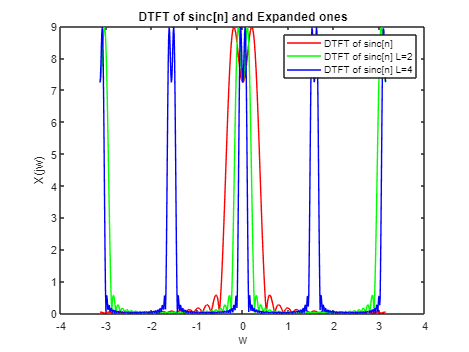

[xd_L2,n_L2] = Expander(xd_t,n_d,2);
[xd_L4,n_L4] = Expander(xd_t,n_d,4);
[X_main, w] = dtft_manual(xd_t, n_d);
[X_exp2,w] = dtft_manual(xd_L2,n_L2);
[X_exp4,w] = dtft_manual(xd_L4,n_L4);
plot(w,abs(X_main),'r',w,abs(X_exp2),'g',w,abs(X_exp4),'b');
title('DTFT of sinc[n] and Expanded ones')
xlabel('w'); ylabel('X(jw)');
legend('DTFT of sinc[n]','DTFT of sinc[n] L=2','DTFT of sinc[n] L=4')

### As can be seen in figure above, as we increase the L, DTFT of the expanded signal will be shrinked in $\omega
$ axis, but the maximum of signal will be without changes.

#### 
$$\sum_{n=0}^M x{\left[\frac{n}{L}\right]}e^{-j\omega n} =\sum_{n=0}^M x\left\lbrack n\right\rbrack e^{j\omega L} e^{-j\omega n}$$


#### 2-3) we plot the signal in the mentioned interval ([0,35]) and take the signal as an argument to Compressor function and different M's (2, 4, 8) and will plot the signal in time domain.

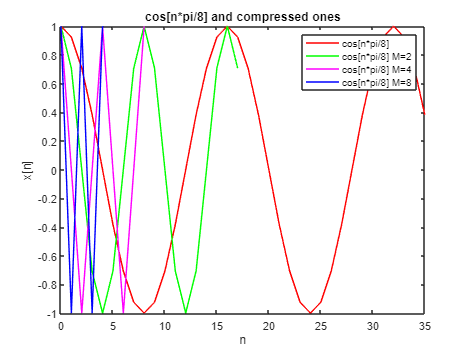

n = 0:1:35;
x_n = cos(n*pi/8);
[compcos1,n1] = compressor(x_n,n, 2);
[compcos2,n2] = compressor(x_n,n, 4);
[compcos3,n3] = compressor(x_n,n, 8);
plot(n,x_n,'r',n1,compcos1,'g',n2,compcos2,'m',n3,compcos3,'b')
title('cos[n*pi/8] and compressed ones')
xlabel('n'); ylabel('x[n]');
legend('cos[n*pi/8]','cos[n*pi/8] M=2','cos[n*pi/8] M=4', 'cos[n*pi/8] M=8')

#### As you can see in Figure above, as we compress the signal by bigger value of M, in time domain, signal will be compressed too.

#### That's because we can say with M = 8, is about zero. It takes one sample in every 8 sample and It occupied little interval.

# 2-4) interpolators are explained at the end of the live scipt file.

#### Theoretically, we can use all of the four interpolator, but in practice and in real wolrd, implementing sinc function as an ideal block is impossible; because it have non zero values in infinite so we cannot implemente this block ideally.

#### 2-5) For $\theta =0$, at furst we create intervals and implement cosine function using that interval. We sample the continuous signal with sampling frequency of 40 Hz to get discrete signal. Then we plot them both in one figure to show  how sampling is done.

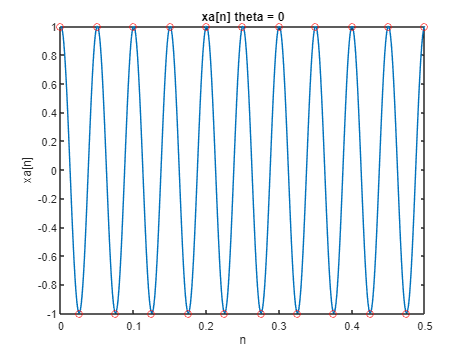

f1 = 1000;
t_5 = 0:1/f1:0.5;
xa_t = cos(40*pi*t_5);

f2 = 40;
xa_n = xa_t(1:f1/f2:length(xa_t));
n = 0:20;
t2_5 = 0:1/f2:0.5;
plot(t_5,xa_t,n/f2,xa_n,'ro')
title('xa[n] theta = 0')
xlabel('n'); ylabel('xa[n]');

#### As you can see, it sampled the maximum and the minimum of the signal.

#### For implementing $\textrm{Cos}\left(40\pi t+\frac{\pi }{6}\right)$ we take actions like the previous one and after sampling the signal, we plot the both to show which part of the signal has been sampled.

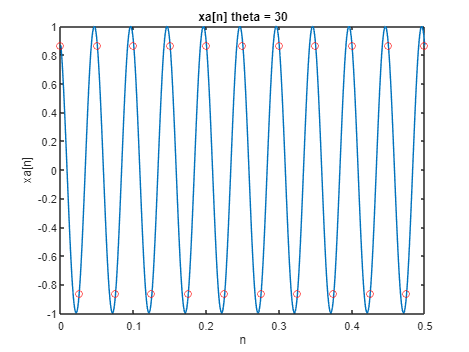

f1 = 1000;
t_5 = 0:1/f1:0.5;
xa_t2 = cos(40*pi*t_5 + pi/6);
f2 = 40;
xa_n2 = xa_t2(1:f1/f2:length(xa_t2));
n = 0:20;
plot(t_5,xa_t2,n/f2,xa_n2,'ro')
title('xa[n] theta = 30')
xlabel('n'); ylabel('xa[n]');

#### As can be seen, sampling points are a little different from maximums and minimums of the signal and that's because of the $\frac{\pi }{6}$ shift in main signal.

#### 
$$\theta =\frac{\pi }{2\;}$$


#### in this signal, we shift it with $\frac{\pi }{2\;}$ so the cosine signal will be converted to $-\textrm{Sin}\left(40\pi t\right)$. With sampling by rate of 40 Hz, we sample zero points of the signal.

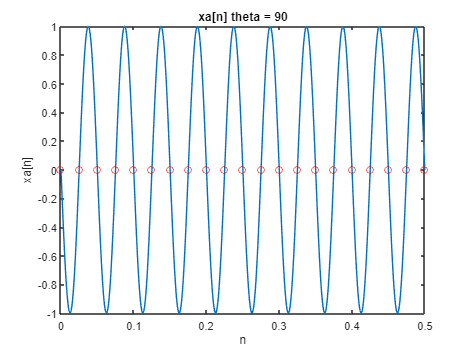

f1 = 1000;
t_5 = 0:1/f1:0.5;
xa_t3 = cos(40*pi*t_5 + pi/2);
f2 = 40;
xa_n3 = xa_t3(1:f1/f2:length(xa_t3));
n = 0:f2/2;
t2_5 = 0:1/f2:0.5;
plot(t_5,xa_t3,t2_5,xa_n3,'ro')
title('xa[n] theta = 90')
xlabel('n'); ylabel('xa[n]');

## `INTERPOLATOR 1: IDEAL INTERPOLATOR`

#### In this part, all of the 3 different signals goes into Expander block to be prepared for entering interpolation block. We start with interpolator $h_1 \left\lbrack n\right\rbrack$. 

#### Expantion coefficient will be 1000/40. And that's beacause the first continuous signal was produced with sampling rate of 1000 Hz and then we change that sampling rate to 40 Hz. so we need 1000/40 = 25 points to take place in between 2 points in signal and get filled.

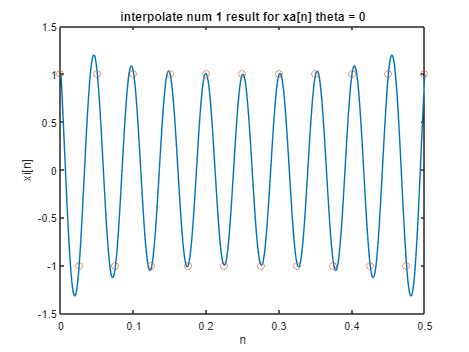

[ex11,nex11] = Expander(xa_n,n,25);
interpolated1_1 = interpolation1(ex11,nex11,25);
plot(t_5,interpolated1_1,n/40,xa_n,'o');
title('interpolate num 1 result for xa[n] theta = 0')
xlabel('n'); ylabel('xi[n]');

#### $h_1 \left\lbrack n\right\rbrack$ interpolate main signal with acceptable accuracy.

Er0_ideal = immse(interpolated1_1,xa_t)

Er0_ideal = 0.1124

#### The mean squared error of ideal interpolator and the signal with no shift is 0.1124.

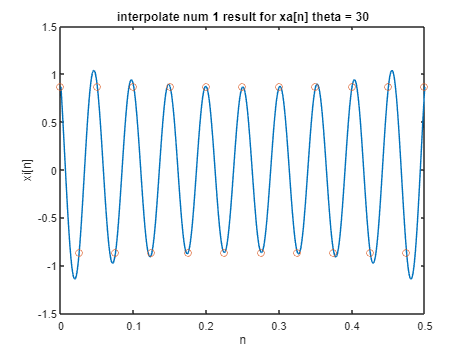

[ex12,nex12] = Expander(xa_n2,n,25);
interpolated2_1 = interpolation1(ex12,nex12,25);
plot(t_5,interpolated2_1,n/40,xa_n2,'o');
title('interpolate num 1 result for xa[n] theta = 30')
xlabel('n'); ylabel('xi[n]');

#### $h_1 \left\lbrack n\right\rbrack$ interpolate main signal with acceptable accuracy but not as good as the previous one.

Er30_ideal = immse(interpolated2_1,xa_t2)

Er30_ideal = 0.2090

#### The mean squared error of ideal interpolator and the signal with $\frac{\pi }{6}$ shift is 0.2090

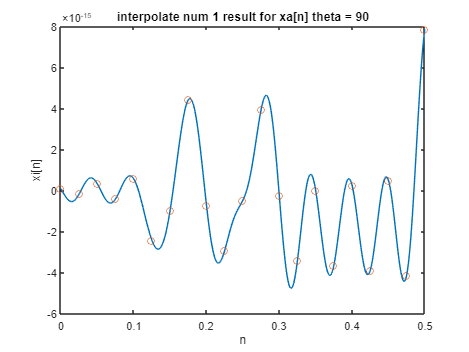

[ex13,nex13] = Expander(xa_n3,n,25);
interpolated3_1 = interpolation1(ex13,nex13,25);
plot(t_5,interpolated3_1,n/40,xa_n3,'o');
title('interpolate num 1 result for xa[n] theta = 90')
xlabel('n'); ylabel('xi[n]');

Er90_ideal = immse(interpolated3_1,xa_t3)

Er90_ideal = 0.4990

#### The main signal cannot be reproduced because we didn't take good and main samples from continous one. Also it can be seen that the Mean squared error of this interpolated signal and main one is high (0.4990).

## `INTERPOLATOR 2: LINEAR INTERPOLATOR`

#### In this part, all of the 3 different signals goes into Expander block to be prepared for entering linear interpolation block .

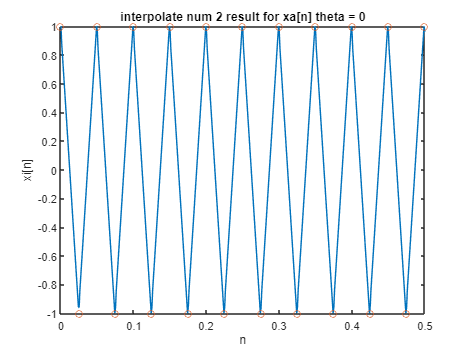

[ex1,nex1] = Expander(xa_n,n,25);
interpolated1_2 = interpolation2(ex1,nex1,25);
plot(t_5,interpolated1_2,n/40,xa_n,'o');
title('interpolate num 2 result for xa[n] theta = 0')
xlabel('n'); ylabel('xi[n]');

Er0_linear = immse(interpolated1_2,xa_t)

Er0_linear = 0.0287

#### The mean squared error of interpolated signal with no shift and main one is 0.0287 which is smaller that the error for Ideal block.

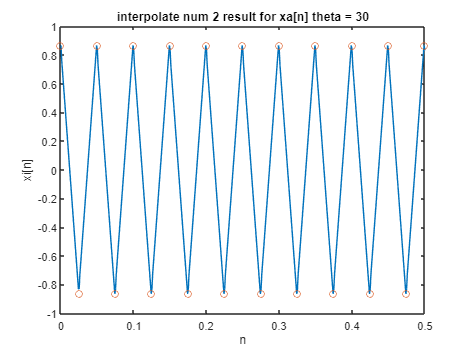

[ex2,nex2] = Expander(xa_n2,n,25);
interpolated2_2 = interpolation2(ex2,nex2,25);
plot(t_5,interpolated2_2,n/40,xa_n2,'o');
title('interpolate num 2 result for xa[n] theta = 30')
xlabel('n'); ylabel('xi[n]');

Er30_linear = immse(interpolated2_2,xa_t2)

Er30_linear = 0.1034

#### The mean squared error of interpolated signal with $\frac{\pi }{6}$ shift and main one is 0.1034 which is smaller that the error for Ideal block.

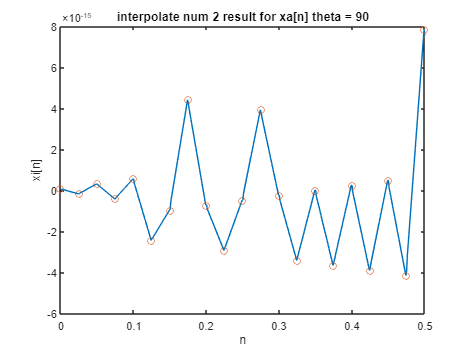

[ex3,nex3] = Expander(xa_n3,n,25);
interpolated3_2 = interpolation2(ex3,nex3,25);
plot(t_5,interpolated3_2,n/40,xa_n3,'o');
title('interpolate num 2 result for xa[n] theta = 90')
xlabel('n'); ylabel('xi[n]');

Er90_linear = immse(interpolated3_2,xa_t3)

Er90_linear = 0.4990

#### It can be seen that the Mean squared error of this interpolated signal with $\frac{\pi }{2}$ shift and main one is high (0.4990) and it's same as MSE of Ideal block.

## `INTERPOLATOR 3: ZERO-ORDER HOLD INTERPOLATOR`

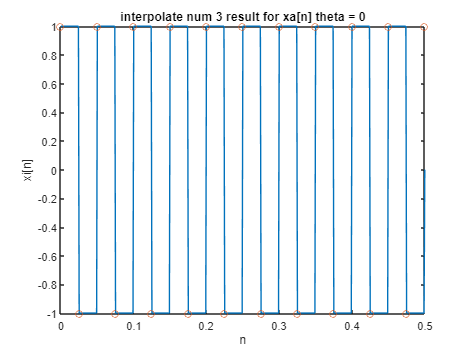

[ex31,nex31] = Expander(xa_n,n,25);
interpolated1_3 = interpolation3(ex31,nex31,25);
plot(t_5,interpolated1_3,n/40,xa_n,'o')
title('interpolate num 3 result for xa[n] theta = 0')
xlabel('n'); ylabel('xi[n]');

Er0_zoh = immse(interpolated1_3,xa_t)

Er0_zoh = 1.4192

#### Compare to the two previous interpolators, the MSE of this interpolator is high for signal with no shift.

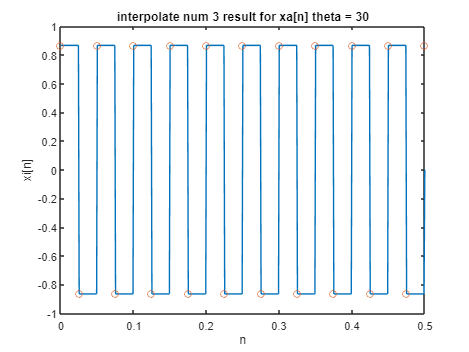

[ex32,nex32] = Expander(xa_n2,n,25);
interpolated2_3 = interpolation3(ex32,nex32,25);
plot(t_5,interpolated2_3,n/40,xa_n2,'o')
title('interpolate num 3 result for xa[n] theta = 30')
xlabel('n'); ylabel('xi[n]');

Er30_zoh = immse(interpolated2_3,xa_t2)

Er30_zoh = 1.7386

#### It's still higher error tham the previous two interpolator with signal with  $\frac{\pi }{6\;}\;$shift. (1.7386)

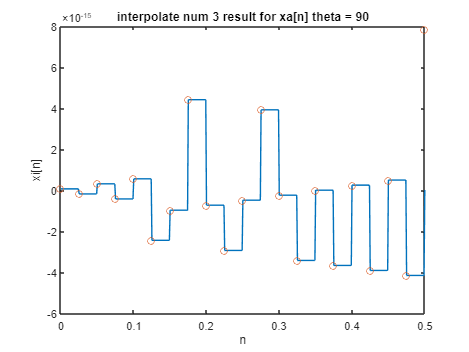

[ex33,nex33] = Expander(xa_n3,n,25);
interpolated3_3 = interpolation3(ex33,nex33,25);
plot(t_5,interpolated3_3,n/40,xa_n3,'o')
title('interpolate num 3 result for xa[n] theta = 90')
xlabel('n'); ylabel('xi[n]');

Er90_zoh = immse(interpolated3_3,xa_t3)

Er90_zoh = 0.4990

## `INTERPOLATOR 4: CUBIC SPLINE INTERPOLATOR`

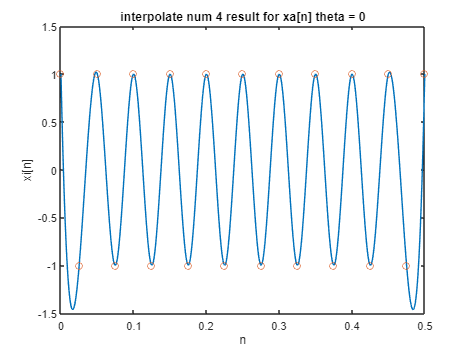

[ex41,nex41] = Expander(xa_n,n,25);
interpolated1_4 = interpolation4(ex41,nex41,40,25);
plot(t_5,interpolated1_4,n/40,xa_n,'o')
title('interpolate num 4 result for xa[n] theta = 0')
xlabel('n'); ylabel('xi[n]');

Er0_cs = immse(interpolated1_4,xa_t)

Er0_cs = 0.1130

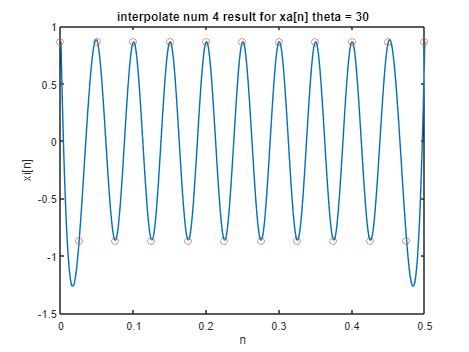

[ex42,nex42] = Expander(xa_n2,n,25);
interpolated2_4 = interpolation4(ex42,nex42,40,25);
plot(t_5,interpolated2_4,n/40,xa_n2,'o')
title('interpolate num 4 result for xa[n] theta = 30')
xlabel('n'); ylabel('xi[n]');

Er30_cs = immse(interpolated2_4,xa_t2)

Er30_cs = 0.2095

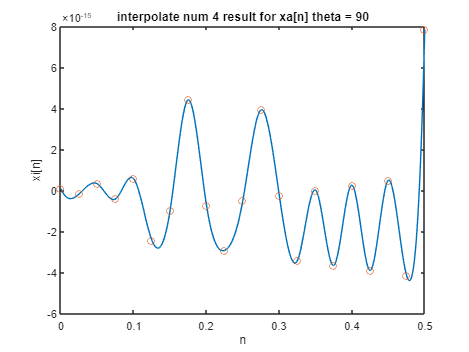

[ex43,nex43] = Expander(xa_n3,n,25);
interpolated3_4 = interpolation4(ex43,nex43,40,25);
plot(t_5,interpolated3_4,n/40,xa_n3,'o')
title('interpolate num 4 result for xa[n] theta = 90')
xlabel('n'); ylabel('xi[n]');

Er90_cs = immse(interpolated3_4,xa_t3)

Er90_cs = 0.4990

#### $\theta =0$:

#### Ideal MSE = 0.1124

#### Linear MSE = 0.287

#### ZO hold MSE = 1.4192

#### Cubic spline MSE = 0.1130

#### $\theta =\frac{\pi }{6}$:

#### Ideal MSE = 0.2090

#### Linear MSE = 0.1034

#### ZO hold MSE = 1.7386

#### Cubic spline MSE = 0.2095

#### $\theta =\frac{\pi }{2}$:

#### Ideal MSE = 0.4990

#### Linear MSE = 0.4990

#### ZO hold MSE = 0.4990

#### Cubic spline MSE = 0.4990

### As can be seen, the Ideal interpolator and cubic spline interpolators have the lowest errors among these three interpolators and have the most smooth results.

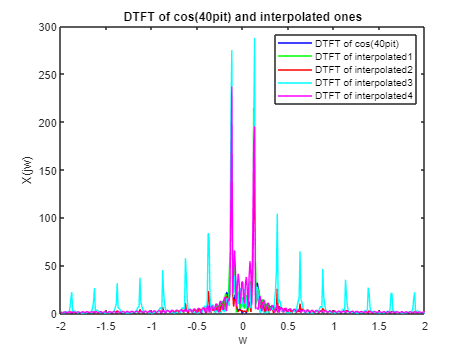

n_ad = 0:0.5*f1;
[X0_main, w] = dtft_manual(xa_t, n_ad);
[X0_inter1,w] = dtft_manual(interpolated1_1,n_ad);
[X0_inter2,w] = dtft_manual(interpolated1_2,n_ad);
[X0_inter3,w] = dtft_manual(interpolated1_3,n_ad);
[X0_inter4,w] = dtft_manual(interpolated1_4,n_ad);
plot(w,abs(X0_main),'b',w,abs(X0_inter1),'g',w,abs(X0_inter2),'r',w,abs(X0_inter3),'c',w,abs(X0_inter4),'m');
title('DTFT of cos(40pit) and interpolated ones')
xlabel('w'); ylabel('X(jw)');
legend('DTFT of cos(40pit)','DTFT of interpolated1','DTFT of interpolated2','DTFT of interpolated3', 'DTFT of interpolated4')
ax = gca;
ax.XLim = [-2 2];

#### We can see in figure above that the DTFT of Cos(40*pi*t) is symmetric and there are two kinds of impulses at $\omega
$ = 0.02 but in different interpolators, it will be appeared in asymmetric way. the best symmetric ones are the interpolated with cubic spline and ideal interpolater.

#### There is another point that have to be mentioned about the repetation of the impulses and the reason for that is we cannot reproduce the exact Cosine-type function. So it's not only have 2 impulses.

#### The other results of interpolating is having noise in frequency domain. As you can see, the interpolator num3 create the most noises in the DTFT of signal.

#### The nearest DTFTs to the DTFT of signal are results from interpolator 4 (cubic spline) and interpolator 1 (Ideal).

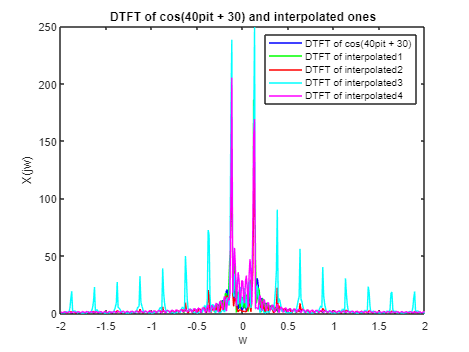

n_ad = 0:0.5*f1;
[X30_main, w] = dtft_manual(xa_t2, n_ad);
[X30_inter1,w] = dtft_manual(interpolated2_1,n_ad);
[X30_inter2,w] = dtft_manual(interpolated2_2,n_ad);
[X30_inter3,w] = dtft_manual(interpolated2_3,n_ad);
[X30_inter4,w] = dtft_manual(interpolated2_4,n_ad);
plot(w,abs(X30_main),'b',w,abs(X30_inter1),'g',w,abs(X30_inter2),'r',w,abs(X30_inter3),'c',w,abs(X30_inter4),'m');
title('DTFT of cos(40pit + 30) and interpolated ones')
xlabel('w'); ylabel('X(jw)');
legend('DTFT of cos(40pit + 30)','DTFT of interpolated1','DTFT of interpolated2','DTFT of interpolated3', 'DTFT of interpolated4')
ax = gca;
ax.XLim = [-2 2];

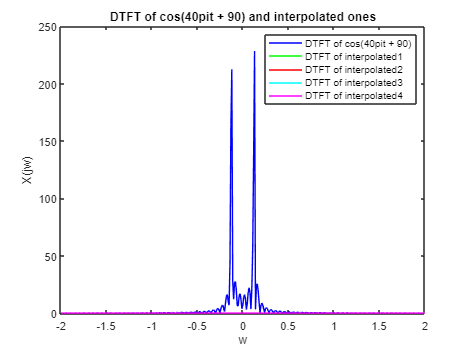

n_ad = 0:0.5*f1;
[X90_main, w] = dtft_manual(xa_t3, n_ad);
[X90_inter1,w] = dtft_manual(interpolated3_1,n_ad);
[X90_inter2,w] = dtft_manual(interpolated3_2,n_ad);
[X90_inter3,w] = dtft_manual(interpolated3_3,n_ad);
[X90_inter4,w] = dtft_manual(interpolated3_4,n_ad);
plot(w,abs(X90_main),'b',w,abs(X90_inter1),'g',w,abs(X90_inter2),'r',w,abs(X90_inter3),'c',w,abs(X90_inter4),'m');
title('DTFT of cos(40pit + 90) and interpolated ones')
xlabel('w'); ylabel('X(jw)');
legend('DTFT of cos(40pit + 90)','DTFT of interpolated1','DTFT of interpolated2','DTFT of interpolated3', 'DTFT of interpolated4')
ax = gca;
ax.XLim = [-2 2];

#### As we can see in figure above, the DTFT of interpolated signals are about zero. The reason of that is the sampling rate for converting continuous signal to discrete signal, is below the nyquist rate and also because of the high amount of shifting, only takes the samples that had zero values. So the main signal cannot be reconstruct. It can be concluded that shifting the main signal is effective in reproducing the signal.

# PART 3) Z-TRANSFORM OPTIONAL

#### 3-1) $\begin{array}{l}
H\left(z\right)=\frac{Y\left(z\right)}{X\left(z\right)}=\frac{\frac{5}{6}z^2 -\frac{35}{36}z-\frac{1}{2}}{z^2 -\frac{1}{6}z-\frac{1}{3}}=\frac{\frac{5}{6}-\frac{35}{36}z^{-1} -\frac{1}{2}z^{-2} }{1-\frac{1}{6}z^{-1} -\frac{1}{3}z^{-2} }\Rightarrow \frac{5}{6}X\left(z\right)-\frac{35}{36}z^{-1} X\left(z\right)-\frac{1}{2}z^{-2} X\left(z\right)=Y\left(z\right)-\frac{1}{6}z^{-1} Y\left(z\right)-\frac{1}{3}z^{-2} Y\left(z\right)\overset{Z^{-1} }{\Rightarrow} \\
\frac{5}{6}x\left\lbrack n\right\rbrack -\frac{35}{36}x\left\lbrack n-1\right\rbrack -\frac{1}{2}x\left\lbrack n-2\right\rbrack =y\left\lbrack n\right\rbrack -\frac{1}{6}y\left\lbrack n-1\right\rbrack -\frac{1}{3}y\left\lbrack n-2\right\rbrack 
\end{array}$

x_n = [1, zeros(1,99)];
x_n_1 = [0, 1, zeros(1,98)];
x_n_2 = [0, 0, 1,zeros(1,97)];
yn_1_zero = 0;
yn_2_zero = 0;
y = zeros(1, 100);
for i=1:100
    y(i) = (5/6)*x_n(i) - (35/36)*x_n_1(i) - (1/2)*x_n_2(i) + (1/6)*yn_1_zero + (1/3)*yn_2_zero;
    yn_2_zero = yn_1_zero;
    yn_1_zero = y(i);
end
y

y =     0.8333   -0.8333   -0.3611   -0.3380   -0.1767   -0.1421   -0.0826   -0.0611   -0.0377   -0.0267   -0.0170   -0.0117   -0.0076   -0.0052   -0.0034   -0.0023   -0.0015   -0.0010   -0.0007   -0.0005   -0.0003   -0.0002   -0.0001   -0.0001   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000


#### a)First we define 3 arrays with the size of 100 as $\delta \left(\left\lbrack n\right\rbrack \right.$, $\delta \left(\left\lbrack n-1\right\rbrack \right.$, $\delta \left(\left\lbrack n-2\right\rbrack \right.$which have only one index with value 1. after that we initialize the y[-1] and y[-2] with zero and start construcring y[n] index by index. this action will be done by updating y[n-1] and y[n-2] with y[n] and y[n-1].

n = 1:100;
n2 = 1:99;
n3 = 1:98;
x_n_step =(2 - 0.8*(0.5).^n) .* ones(1,100);
x_n_1_step = [1, (2 - 0.8*(0.5).^n2) .* ones(1,99)];    
x_n_2_step = [1, 1, (2 - 0.8*(0.5).^n3) .* ones(1,98)];
yn_1_zero_step = 3;
yn_2_zero_step = -1;
y_step = zeros(1, 100);
for i=1:100
    y_step(i) = (5/6)*x_n_step(i) - (35/36)*x_n_1_step(i) - (1/2)*x_n_2_step(i) + (1/6)*yn_1_zero_step + (1/3)*yn_2_zero_step;
    yn_2_zero_step = yn_1_zero_step;
    yn_1_zero_step = y_step(i);
end

y_step

y_step =     0.0278    0.4491   -0.8826   -1.1196   -1.6808   -1.8922   -2.1340   -2.2545   -2.3600   -2.4202   -2.4666   -2.4950   -2.5155   -2.5285   -2.5376   -2.5435   -2.5476   -2.5502   -2.5520   -2.5532   -2.5540   -2.5545   -2.5549   -2.5551   -2.5552   -2.5553   -2.5554   -2.5555   -2.5555   -2.5555   -2.5555   -2.5555   -2.5555   -2.5555   -2.5556   -2.5556   -2.5556   -2.5556   -2.5556   -2.5556   -2.5556   -2.5556   -2.5556   -2.5556   -2.5556   -2.5556   -2.5556   -2.5556   -2.5556   -2.5556


#### b)This part is like the previous part. exept the initial value of y[-1] and y[-2] with the given values and x[-1] and x[-2] with 1 and 1.

#### For initialing the value of x[n], we act like initial values of y[n] exept that x[n] and x[n-1] and x[n-2] are lists and the other indeces (exept first or first and second) should be filled with the actual form of signal.

#### c) Before using filter function, we have to define a and b lists for coefficient of x[n]s and y[n]s. then print the first 20 values of the answer of the system.

b = [5/6 -35/36 -1/2];
a = [1 -1/6 -1/3];
y_filt = filter(b,a,x_n);
y_filt(1:20)

ans =     0.8333   -0.8333   -0.3611   -0.3380   -0.1767   -0.1421   -0.0826   -0.0611   -0.0377   -0.0267   -0.0170   -0.0117   -0.0076   -0.0052   -0.0034   -0.0023   -0.0015   -0.0010   -0.0007   -0.0005


#### Compare to the result of 'y', we got the same values which shows that the answer that we got is correct.

#### We do that for part 2:

xi1 = filtic(b,a,Y1,X1);
yzi = filter(b,a,x_n_step,xi1)

yzi =    1.4989 - 0.0250i   1.1943 - 0.0042i  -0.2680 - 0.0090i  -0.7688 - 0.0029i  -1.4175 - 0.0035i  -1.7314 - 0.0015i  -2.0194 - 0.0014i  -2.1818 - 0.0008i  -2.3097 - 0.0006i  -2.3875 - 0.0004i  -2.4444 - 0.0003i  -2.4804 - 0.0002i  -2.5057 - 0.0001i  -2.5220 - 0.0001i  -2.5333 - 0.0000i  -2.5406 - 0.0000i  -2.5456 - 0.0000i  -2.5489 - 0.0000i  -2.5511 - 0.0000i  -2.5526 - 0.0000i  -2.5536 - 0.0000i  -2.5542 - 0.0000i  -2.5547 - 0.0000i  -2.5550 - 0.0000i  -2.5552 - 0.0000i  -2.5553 - 0.0000i  -2.5554 - 0.0000i  -2.5554 - 0.0000i  -2.5555 - 0.0000i  -2.5555 - 0.0000i  -2.5555 - 0.0000i  -2.5555 - 0.0000i  -2.5555 - 0.0000i  -2.5555 - 0.0000i  -2.5555 - 0.0000i  -2.5556 - 0.0000i  -2.5556 - 0.0000i  -2.5556 - 0.0000i  -2.5556 - 0.0000i  -2.5556 - 0.0000i  -2.5556 - 0.0000i  -2.5556 - 0.0000i  -2.5556 - 0.0000i  -2.5556 - 0.0000i  -2.5556 - 0.0000i  -2.5556 - 0.0000i  -2.5556 - 0.0000i  -2.5556 - 0.0000i  -2.5556 - 0.0000i  -2.5556 - 0.0000i


#### for taking the initial values as an input, we have to use filtic function. This function by taking the coefficient arrays of x and y, and also the initial values of x and y, takes out the answer of the system. As you can see, the result are the same.

#### d) For plotting the Zero-input response, after using filtic function which was explained above, we take the input of filter function a series of zero which means zero inputting

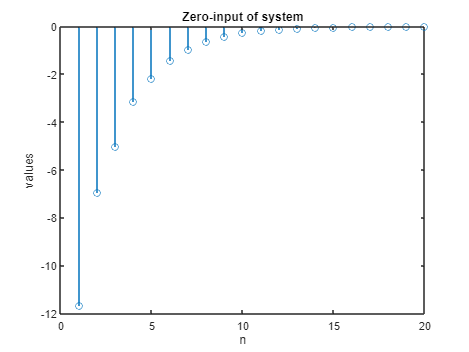

a = [6 -1 -2];
b = [30 -35 -36];
X = [1 1];
Y = [3 -1];
xi0 = filtic(b,a,Y,X);
yzi = filter(b,a,zeros(1,20),xi0);
stem(yzi)
title('Zero-input of system')
xlabel('n')
ylabel('values')

## `Functions`

#### 1-1)DTFT function  will be implemented like down below:

#### 
$$X\left(j\omega \right)=\sum_{n=-\infty }^{\infty } x\left\lbrack n\right\rbrack e^{-j\omega }$$


#### It will be good to be mentioned that after calculating the DTFT of signal, the interval of DTFT should be output of this function for ploting the DTFT. the new interval for $\omega$, will be like $R_M \left\lbrack n\right\rbrack$.

function [X,w] = dtft_manual(x, M)
w=-pi:0.01:pi;
n=0:length(M)-1;
for i=1:length(w)
    X(i)=0;
    for k=1:length(x)
          X(i)=X(i)+(x(k).*exp(-j.*w(i).*n(k)));
      end
end
end

#### 1-2)

#### 
$$y\left\lbrack n\right\rbrack =\sum_{m=0}^M b_m x\left\lbrack n-m\right\rbrack -\sum_{l=1}^N a_l y\left\lbrack n-l\right\rbrack$$


#### Fourier transform:

#### 
$$Y\left(e^{j\omega } \right)+a_1 e^{-j\omega } Y\left(e^{j\omega } \right)+a_2 e^{-\textrm{j2}\omega } Y\left(e^{j\omega } \right)+\ldotp \ldotp \ldotp =b_0 X\left(e^{j\omega } \right)+b_1 e^{-j\omega } X\left(e^{j\omega } \right)+\ldotp \ldotp \ldotp$$


#### 
$$\frac{Y\left(e^{j\omega } \right)}{X\left(e^{j\omega } \right)}=H\left(e^{j\omega } \right)=\frac{b_0 +b_1 e^{-j\omega } +b_2 e^{-\textrm{j2}\omega } +\ldotp \ldotp \ldotp }{1+a_1 e^{-j\omega } +a_2 e^{-\textrm{j2}\omega } +a_3 e^{-\textrm{j3}\omega } +\ldotp \ldotp \ldotp }$$


#### for implementing $H\left(e^{j\omega } \right)$, after getting a and b vector and $\omega
$ interval as inputs of this function, we loop through $\omega
$ and in every iteration we calculate $a_n e^{-j\omega n}$ and sum it to their previous values.

#### In the end, we devide the $a_n e^{-j\omega n}$ over $b_m e^{-j\omega m}$ to calculate $H\left(e^{j\omega } \right)$.

function H_jw = diff_resp(a, b, W)
    
    a = [1,a];
    H_jw = zeros(1, length(W));
    for w = 1:length(W)
        e_coeff_a = 0;
        e_coeff_b = 0;
        for k = 1:length(a)
            e_coeff_a = e_coeff_a + a(k)*exp(-1i*W(w)*(k-1));
        end
        for k = 1:length(b)
            e_coeff_b = e_coeff_b + b(k)*exp(-1i*W(w)*(k-1));
        end
        H_jw(w) = (e_coeff_b)/e_coeff_a;
    end
end

function [compressed_x,compressed_nx] = compressor (x,nx,M)
    for j = 1:M
        if (mod(nx(j),M) == 0)
            i = j;
        end
    end
    compressed_x = x(i:M:length(x));
    compressed_nx = nx(i:M:length(nx))/M;
end

function [y,ny] = Expander (x,nx,L)
    y =[];
    j = L-1;
    for i=1:length(x)
        y = [y x(i)];
        if(i~=length(x))
            for m=1:j
                y = [y 0];
            end
        end
    end
    ny = (L*nx(1)):(L*nx(length(nx)));
end

#### 2-4) first, we have to implement interpolator$h_1 \left\lbrack n\right\rbrack$. This interpolator, interpolate signal with Sinc function. in other words, it fills the gap between the 2 point of the signal with sinc function. It's good to be mentioned that this function, takes the expanded signal as an input. For plotting the signal, we need the interval of interpolated Signal which is different from the main signal.

#### 
$$h_1 {\left[n\right]}=\frac{\sin {\left(\frac{n\pi }{L}\right)}}{\frac{n\pi }{L}}$$


function interpolated_H1_x = interpolation1(x,n, L)
     n1 = n(1:L:length(n))/L;
    xc = x(1:L:length(x));
    interpolated_H1_x = xc * sinc(ones(length(n1),1)*n/L - n1'*ones(1,length(n)));
   
end

#### for implementing interpolator $h_2 \left\lbrack n\right\rbrack \;$which is known for `Linear interpolator`, we have to sum up the values in x with the old interval times the absolute value of n fractured by the factor L as the value of changes. For correcting the interpolated interval, we check different intervals to get to the right one.

function interpolated_h2_x = interpolation2(x,n_x, L)
      x_lin = [zeros(1,L-1) x zeros(1,L-1)];
      n_lin = [-L+1:0 n_x length(n_x):length(n_x)+L-1];
      interpolated_h2_x = zeros(1,length(n_x));
      for i = n_x
        interpolated_h2_x(i+1) = sum(x_lin((i+1):(i+2*L-1)).*(1-abs(i-n_lin((i+1):(i+2*L-1)))/L));
      end
end

#### Interpolator $h_3 \left\lbrack n\right\rbrack \;$ represents `Zero-order hold interpolator`. After expantion of the signal, it fills the gap with one. It's better to be said that it will be convolved with the expanded signal.

function interpolated_h3_x = interpolation3(x,n_x, L)
      
      h3_n = zeros(1,L-1);
      for i=1:L
          h3_n(i) = 1;
      end
      interpolated_h3_x = conv(x(1:20*(L-1)-3), h3_n);
end

#### For Implementing $h_4 \left\lbrack n\right\rbrack \;$interpolator which is known as `cubic spline interpolator`, we also need to use spline function. It takes interval of expanded signal, frequency of signal and also discrete form of expanded signal as inputs and the output will be the interpolated signal.

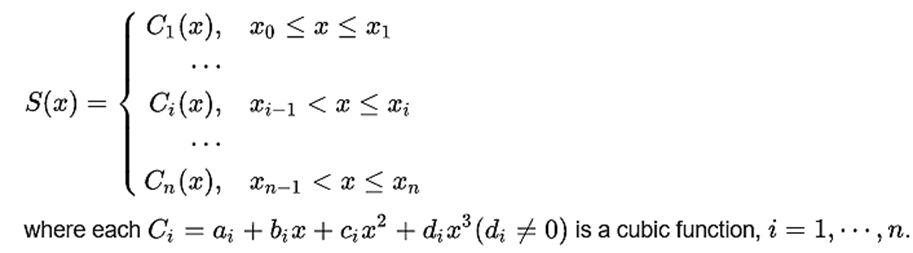

function interpolated_h4_x = interpolation4(x,n,fs, L)
      n1 = n(1:L:length(n))/L;
      xc = x(1:L:length(x));
      t = n / (fs*L);
      interpolated_h4_x = spline(n1/fs,xc,t);
end